# Victoria Strobel 

## Fahrzeugdaten laden

FzgDaten;

FzgDaten geladen


## Bremsvorgang

Eingangsdaten setzen

time_vector = [0 0.6 0.9 1.1 20];
accel_vector = [0 0 -1 -9 -9];
T0 = 0.6;
T1 = 0.3;
T2 = 0.2;
t_v = [0 T0 T0+T1 T0+T1+T2 20];
ax1 = -1;
ax2 = -9;
a_v = [0 0 ax1 ax2 ax2];

Bremsvorgang simulieren

model = 'Bremsvorgang';
load_system(model)
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
simIn = setBlockParameter(simIn, "Bremsvorgang/Repeating_Sequence", "rep_seq_t", mat2str(t_v));
simIn = setBlockParameter(simIn, "Bremsvorgang/Repeating_Sequence", "rep_seq_y", mat2str(a_v));

out = sim(simIn);

Daten auslesen

outputs = out.yout;
t = out.tout;
s = outputs{1}.Values.Data;
v = outputs{2}.Values.Data;
a = outputs{3}.Values.Data;

Beschleunigung darstellen

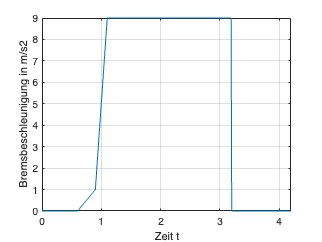

plot(t,-a)
xlabel("Zeit t")
ylabel("Bremsbeschleunigung in m/s2")
ylim([min(-a), max(-a)])
xlim([min(t), max(t)])
grid

Geschwindigkeit darstellen

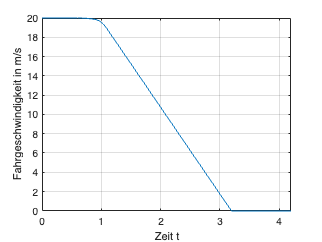

plot(t,v)
xlabel("Zeit t")
ylabel("Fahrgeschwindigkeit in m/s")
ylim([min(v), max(v)])
xlim([min(t), max(t)])
grid

Strecke darstellen

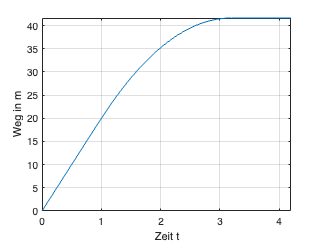

plot(t,s)
xlabel("Zeit t")
ylabel("Weg in m")
ylim([min(s), max(s)])
xlim([min(t), max(t)])
grid

## Tangentialkraftdiagramm

## Querdynamik

### Lenkradwinkelsprung  

#### Nichtlineares Einspurmodell  

model = 'Lenkradwinkelsprung';
load_system(model)
simIn = Simulink.SimulationInput(model);

*Hinweis: Alle Modellparameter, die mit *setModelParameter() *gesetzt werden können, lassen sich folgendermaßen ermitteln:*

Konfiguration der Simulation: $t_\text{Start}=0$, $t_\text{Stop}=t_{\rm end}$, Integration mit fester Zeitschrittweite $\Delta t=0.01$  

tend = 1;
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01',...
    'StartTime','0',...
    'StopTime',num2str(tend));

Konfiguration des Lenkradwinkelsprungs mit $\delta_\text{H}=45\degree $ und $v=60\text{ km/h}$

dH = 45;
v = 60;
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","Time",'0');         % Sprung bei t=0
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","After",string(dH)); % Sprunghöhe in Grad
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/v","Value",string(v));   % Konstante Geschwindigkeit in km/h

Konfiguration der Pacejka-Blöcke mit den Schräglaufsteifikgeiten $C_\text v$, $C_\text h$ und den Achslasten $F_\text{nv}$, $F_\text{nh}$

simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));
applyToModel(simIn) % nicht unbedingt notwendig

Lenkradwinkelsprung simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
outputPsip = getElement(outputs,'psip');
t    = outputPsip.Values.Time;
psip = outputPsip.Values.Data;

Darstellung der Giergeschwindigkeit $\dot\psi$ über $t$ des nichtlinearen und des linearen Einspurmodells 

plot(t,psip)
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\dot{\psi}$ $[^\circ/s]$','interpreter','latex')
title (['Lenkradwinkelsprung mit $\delta_{\rm H} = $' num2str(dH) '$^\circ$ und $v =$ ' num2str(v) ' km/h'] , 'Interpreter','latex'  )
legend('Nichtlinear','Linear','Location','southeast')

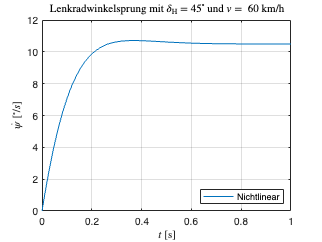

grid